# ECE 132A Project

## By: Warren Pagsuguiron

% create parameters
T = 1; R_s = 1 / T;
F_s = 16;
rolloff = 0.5;
N = [1.6e5 1.6e6 1.6e7];
P = [2 4 8];
fig = 1;

### 2.

p = P(1)

p = 2

n = 160000

fig = 1

frqs =    -8.0000
   -7.9999
   -7.9998
   -7.9997
   -7.9996
   -7.9995
   -7.9994
   -7.9993
   -7.9992
   -7.9991


n = 1600000

fig = 2

frqs =    -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -7.9999
   -7.9999
   -7.9999
   -7.9999


n = 16000000

fig = 3

frqs =    -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000


for n = N
    n
    figure(fig)
    fig
    fig = fig + 1;
    frqs = (-n/2:(n/2)-1)'*F_s/n
    semilogy(frqs/p,fftshift(abs(fft(yrx(1:n).^p))))
    ax = gca;
    chart = ax.Children(1);
    datatip(chart,0.6008,383.3);
end

p = P(2)

p = 4

n = 160000

fig = 4

frqs =    -8.0000
   -7.9999
   -7.9998
   -7.9997
   -7.9996
   -7.9995
   -7.9994
   -7.9993
   -7.9992
   -7.9991


n = 1600000

fig = 5

frqs =    -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -7.9999
   -7.9999
   -7.9999
   -7.9999


n = 16000000

fig = 6

frqs =    -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000


for n = N
    n
    figure(fig)
    fig
    fig = fig + 1;
    frqs = (-n/2:(n/2)-1)'*F_s/n
    semilogy(frqs/p,fftshift(abs(fft(yrx(1:n).^p))))
end

p = P(3)

p = 8

n = 160000

fig = 7

frqs =    -8.0000
   -7.9999
   -7.9998
   -7.9997
   -7.9996
   -7.9995
   -7.9994
   -7.9993
   -7.9992
   -7.9991


n = 1600000

fig = 8

frqs =    -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -7.9999
   -7.9999
   -7.9999
   -7.9999


n = 16000000

fig = 9

frqs =    -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000
   -8.0000


for n = N
    n
    figure(fig)
    fig
    fig = fig + 1;
    frqs = (-n/2:(n/2)-1)'*F_s/n
    semilogy(frqs/p,fftshift(abs(fft(yrx(1:n).^p))))
end

frEst = 0.60085 * (N(1)/F_s)

frEst = 6.0085e+03

yderot = yrx .* exp(-2i*pi*frEst*(0:length(yrx)-1)'/F_s);

### 3.

hrrc = rrc((-6:1/F_s:6)',rolloff,1)/F_s

hrrc =     0.0003
    0.0003
    0.0002
    0.0002
    0.0001
    0.0000
   -0.0001
   -0.0002
   -0.0003
   -0.0003


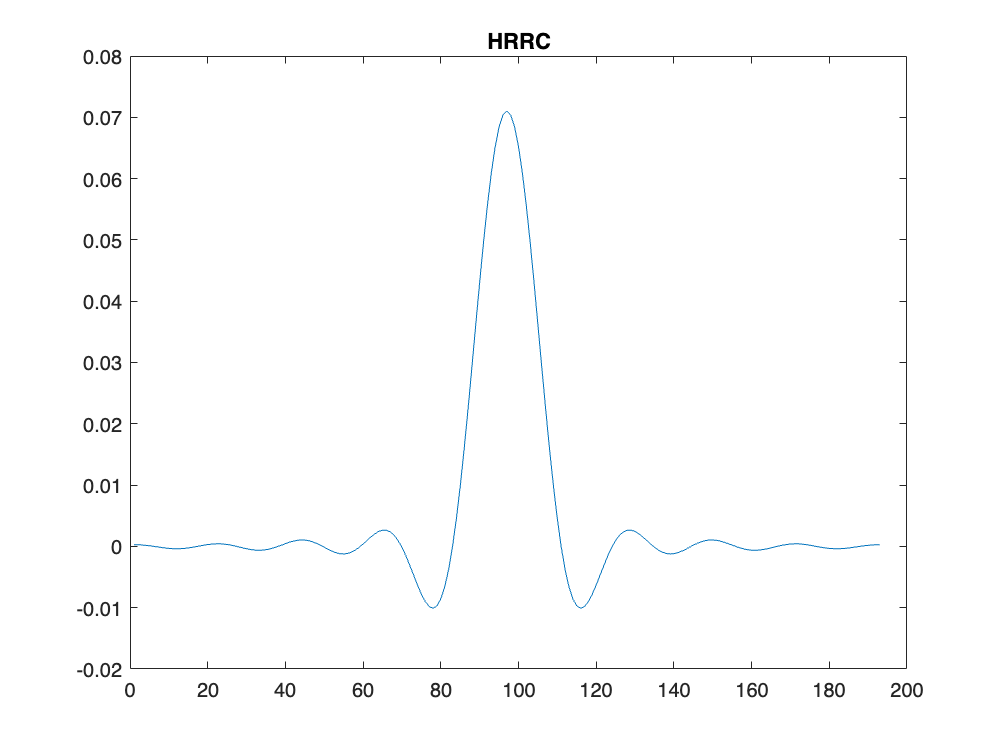

plot(hrrc)
title('HRRC');

### 6.

chosen_n = N(3)

chosen_n = 16000000

phase_offset = 7

phase_offset = 7


preambleSig = conv(upsample([-1;1;-1;1;-1;1;-1;1;-1;1],F_s),hrrc,"full");
preambleSig = preambleSig(phase_offset*F_s+1:end-phase_offset*F_s);
plot(real(xcorr(yderot(1:chosen_n),preambleSig)))